# DC 모터 위치 : PID 제어기 설계 (한글판)

원문 : Control Tutorials for MATLAB and Simulink — DC Motor Position: PID Controller Design 한글 정리 : 제어시스템설계 · 충남대학교 자율운항시스템공학과

이 문서에서 하는 것

- P, PI, PID 를 차례로 붙여 가며 **각 항이 무슨 일을 하는지** 본다

- 외란이 있을 때 무엇이 달라지는지 본다

- 사양을 만족하는 PID 를 하나 만든다

오늘 쓰는 MATLAB 명령 — `tf`, `feedback`, `step`, `stepinfo`

clc; close all;
s = tf('s');

## 1. 제어 대상과 구조

DC 모터의 **위치** 모델은 속도 모델을 한 번 더 적분한 것입니다.


$$P(s) = \frac{\Theta(s)}{V(s)} = \frac{K}{s\left[(Js+b)(Ls+R) + K^2\right]} \qquad \left[\frac{\mathrm{rad}}{\mathrm{V}}\right]$$


분모에 $s$ 가 하나 더 있는 것이 속도 모델과의 유일한 차이입니다. 그 $s$ 하나 때문에 **타입 1** 이 되고, 계단 지령의 정상상태 오차가 $0$ 이 됩니다.

제어 구조는 이렇습니다. 외란 $d$ 가 플랜트 입력으로 들어옵니다.

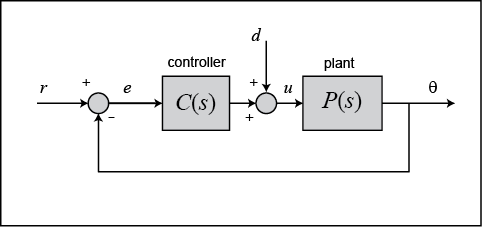

제어기와 외란이 있는 폐루프

J = 3.2284e-6;  b = 3.5077e-6;  K = 0.0274;  R = 4;  L = 2.75e-6;
P_pos = K/(s*((J*s + b)*(L*s + R) + K^2));

fprintf('=== 제어 대상 (DC 모터 위치) ===\n');
P_pos
fprintf('  극점 : %s\n', mat2str(round(pole(P_pos).', 2)));
fprintf('  타입 : %d  (분모의 s 개수)\n\n', sum(abs(pole(P_pos)) < 1e-9));

## 2. 설계 사양

목표 각도 $1\,\mathrm{rad}$ 에 대해 요구는 이렇습니다.

- 정착시간 $0.040$ 초 미만

- 오버슈트 $16\%$ 미만

- **계단 외란이 있어도** 정상상태 오차가 $0$

PID 제어기의 형태는 이것입니다.


$$C(s) = K_p + \frac{K_i}{s} + K_d\,s = \frac{K_d s^2 + K_p s + K_i}{s}$$


세 항이 각각 무슨 일을 하는지 하나씩 붙여 가며 확인합니다.

## 3. P 제어 — 비례항만

제어입력이 오차에 **비례**합니다.


$$u = K_p\,e$$


$K_p$ 를 바꿔 가며 보겠습니다.

t = (0:1e-4:0.2)';
figure;
hold on; grid on;
for Kp = [1 10 21 50]
    Tcl = feedback(Kp*P_pos, 1);
    plot(t, step(Tcl, t), 'LineWidth', 2, 'DisplayName', sprintf('K_p = %d', Kp));
end
yline(1, 'k--', 'HandleVisibility','off');
yline(1.16, 'r:', 'HandleVisibility','off');
xlabel('시간 [s]'); ylabel('각도 [rad]'); ylim([0 1.6]);
legend('Location','southeast');
title('P 제어 : 이득을 키우면 빨라지지만 흔들린다');

fprintf('=== P 제어 ===\n');
fprintf('    Kp    오버슈트[%%]  정착시간[s]   정상상태 오차\n');
fprintf('  ------  -----------  -----------  -------------\n');
for Kp = [1 10 21 50]
    Tcl = feedback(Kp*P_pos, 1);
    ii = stepinfo(Tcl);
    fprintf('  %6d  %11.2f  %11.4f  %13.2e\n', ...
            Kp, ii.Overshoot, ii.SettlingTime, 1-dcgain(Tcl));
end

표에서 확인할 것

- **정상상태 오차가 어떤 **$K_p$** 에서도 **$0$ 입니다. 플랜트에 이미 적분기가 있어 **타입 1** 이기 때문입니다

- $K_p$ 를 키우면 빨라지지만 **더 흔들립니다**

직관으로도 자연스럽습니다. 이득이 크면 같은 오차에도 제어기가 더 세게 밉니다. 빨리 도달하지만 지나쳐 버립니다.

## 3-1. 그런데 외란이 들어오면

지령을 $0$ 으로 두고 **플랜트 입력에 계단 외란**만 넣어 봅니다. 이때의 전달함수는 $\frac{P}{1+CP}$ 입니다.

figure;
hold on; grid on;
for Kp = [1 10 21 50]
    Sd = feedback(P_pos, Kp);
    plot(t, step(Sd, t), 'LineWidth', 2, 'DisplayName', sprintf('K_p = %d', Kp));
end
yline(0, 'k--', 'HandleVisibility','off');
xlabel('시간 [s]'); ylabel('외란 때문에 생긴 각도 [rad]');
legend('Location','southeast');
title('P 제어는 외란을 완전히 없애지 못한다');

fprintf('\n=== P 제어 : 외란에 대한 정상상태 오차 ===\n');
for Kp = [1 10 21 50]
    fprintf('  Kp = %3d : %.5f rad\n', Kp, dcgain(feedback(P_pos, Kp)));
end
fprintf('  --> 이득을 키우면 작아지지만 0 은 아닙니다.\n\n');

## 4. PI 제어 — 적분항을 더한다

적분항은 **오차를 계속 쌓습니다.**


$$u = K_p\,e + K_i\int e\,dt$$


오차가 조금이라도 남아 있으면 적분값이 계속 커지고, 그래서 제어입력이 계속 커져 결국 오차를 밀어 없앱니다. **오차가 정확히 **$0$** 이 되어야만 적분기가 멈춥니다.**

그 덕분에 **외란이 있어도** 정상상태 오차가 $0$ 이 됩니다.

Kp = 21;
figure;
hold on; grid on;
for Ki = [100 200 500]
    C = Kp + Ki/s;
    plot(t, step(feedback(P_pos, C), t), 'LineWidth', 2, ...
         'DisplayName', sprintf('K_i = %d', Ki));
end
plot(t, step(feedback(P_pos, Kp), t), 'k--', 'LineWidth', 1.8, ...
     'DisplayName', 'P 제어만');
yline(0, 'k:', 'HandleVisibility','off');
xlabel('시간 [s]'); ylabel('외란 때문에 생긴 각도 [rad]');
legend('Location','northeast');
title('적분항을 넣으면 외란 오차가 0 으로 사라진다');

fprintf('=== PI 제어 : 외란에 대한 정상상태 오차 ===\n');
for Ki = [100 200 500]
    C = Kp + Ki/s;
    fprintf('  Ki = %3d : %.2e rad\n', Ki, dcgain(feedback(P_pos, C)));
end
fprintf('  --> 정확히 0 입니다.\n\n');

다만 공짜가 아닙니다. 적분기는 극점을 원점에 하나 더 놓는 것이므로 **응답이 느려지고 더 흔들립니다.**

figure;
hold on; grid on;
for Ki = [0 100 200 500]
    if Ki == 0, C = Kp; nm = 'P 만'; else, C = Kp + Ki/s; nm = sprintf('K_i = %d', Ki); end
    plot(t, step(feedback(C*P_pos, 1), t), 'LineWidth', 2, 'DisplayName', nm);
end
yline(1, 'k--', 'HandleVisibility','off');
xlabel('시간 [s]'); ylabel('각도 [rad]'); ylim([0 1.8]);
legend('Location','southeast');
title('적분항은 오차를 없애는 대신 응답을 흔든다');

## 5. PID 제어 — 미분항까지

미분항은 **오차가 얼마나 빨리 변하는지**를 봅니다.


$$u = K_p\,e + K_i\int e\,dt + K_d\,\frac{de}{dt}$$


목표에 빠르게 다가가고 있으면 미리 브레이크를 밟는 셈이라 **오버슈트가 줄고 진동이 잦아듭니다.**

세 항의 역할을 한 줄로 정리하면 이렇습니다.

| 항 | 보는 것 | 하는 일 | 부작용 | |---|---|---|---| | $K_p$ | 지금 얼마나 틀렸나 | 빠르게 만든다 | 흔들린다 | | $K_i$ | 지금까지 얼마나 틀렸나 | 오차를 $0$ 으로 | 느려지고 더 흔들린다 | | $K_d$ | 얼마나 빨리 틀려지나 | 흔들림을 줄인다 | 잡음에 약하다 |

Kp = 21;  Ki = 500;  Kd = 0.05;
C_pid = Kp + Ki/s + Kd*s;
T_pid = feedback(C_pid*P_pos, 1);
i_pid = stepinfo(T_pid);

fprintf('=== PID 설계 결과 (Kp = %g, Ki = %g, Kd = %g) ===\n', Kp, Ki, Kd);
fprintf('  오버슈트   %.2f %%    (요구 16 %% 미만)\n', i_pid.Overshoot);
fprintf('  정착시간   %.4f s   (요구 0.040 s 미만)\n', i_pid.SettlingTime);
fprintf('  지령 오차  %.2e\n', 1-dcgain(T_pid));
fprintf('  외란 오차  %.2e\n\n', dcgain(feedback(P_pos, C_pid)));

t6 = (0:1e-5:0.1)';
figure('Position',[80 80 950 400]);
tiledlayout(1,2,'TileSpacing','compact');
nexttile
plot(t6, step(feedback(Kp*P_pos,1), t6), 'LineWidth', 2); hold on;
plot(t6, step(feedback((Kp+Ki/s)*P_pos,1), t6), 'LineWidth', 2);
plot(t6, step(T_pid, t6), 'LineWidth', 2.5);
yline(1,'k--'); yline(1.16,'r:'); xline(0.04,'r:');
grid on; xlabel('시간 [s]'); ylabel('각도 [rad]'); ylim([0 1.8]);
legend('P','PI','PID','목표','오버슈트 한계','정착시간 한계','Location','southeast');
title('지령 추종');
nexttile
plot(t6, step(feedback(P_pos, Kp), t6), 'LineWidth', 2); hold on;
plot(t6, step(feedback(P_pos, Kp+Ki/s), t6), 'LineWidth', 2);
plot(t6, step(feedback(P_pos, C_pid), t6), 'LineWidth', 2.5);
yline(0,'k--'); grid on;
xlabel('시간 [s]'); ylabel('외란 때문에 생긴 각도 [rad]');
legend('P','PI','PID','Location','northeast');
title('외란 억제');

## 6. 정리

- **P** — 빠르게 만든다. 다만 흔들린다. 플랜트에 적분기가 있으면 지령 오차는 이미 $0$ 이지만 **외란 오차는 남는다**

- **I** — 외란이 있어도 오차를 $0$ 으로 만든다. 대신 느려지고 더 흔들린다

- **D** — 흔들림을 줄인다. 대신 **잡음에 약하다** (7주차에서 자세히)

설계는 대개 이 순서로 합니다.

- 먼저 $K_p$ 로 대략의 빠르기를 잡는다

- 오차가 남으면 $K_i$ 를 더한다

- 너무 흔들리면 $K_d$ 를 더한다

- **매번 검증한다.** 그리고 제어입력도 함께 본다

이 과목의 7 주차(PD·PI)와 11 주차(PID 튜닝) 내용과 이어집니다.